# Plot 2-D Data in MATLAB

`plot` creates a 2-D line plot of the data in `Y` versus the corresponding values in X

## Create a Line Plot

Create `x` as a vector of linearly spaced values between 0 and 2*π*. Use an increment of *π*/100 between the values. Create `y` as sine values of `x`. 

x = 0:pi/100:2*pi;
y = sin(x);

### Basic Plot

Calling the plot function will display the `x` versus `y` data on a scaled vewing domain and range.

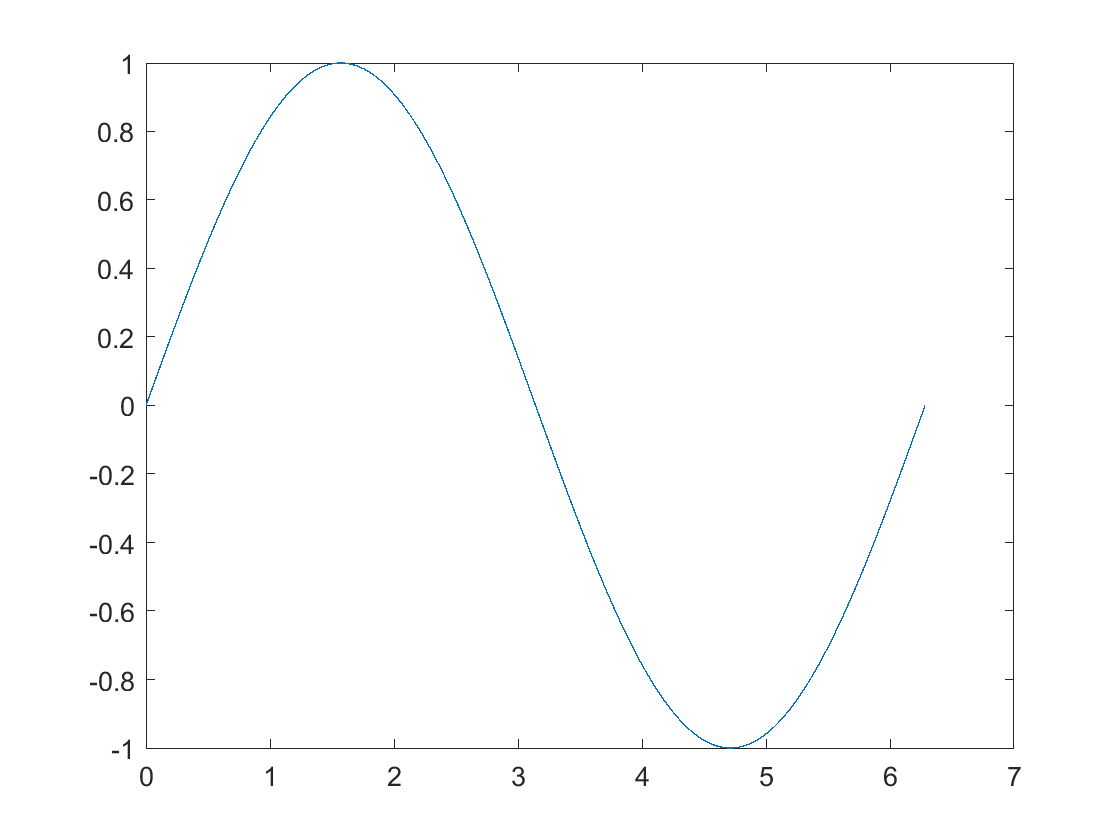

plot(x,y)

## Plot Multiple Lines

Create a second data set with `x` as 100 linearly spaced values between −2*π* and 2*π*. Define `y1` and `y2` as sine and cosine values of `x`. Create a line plot of both sets of data.

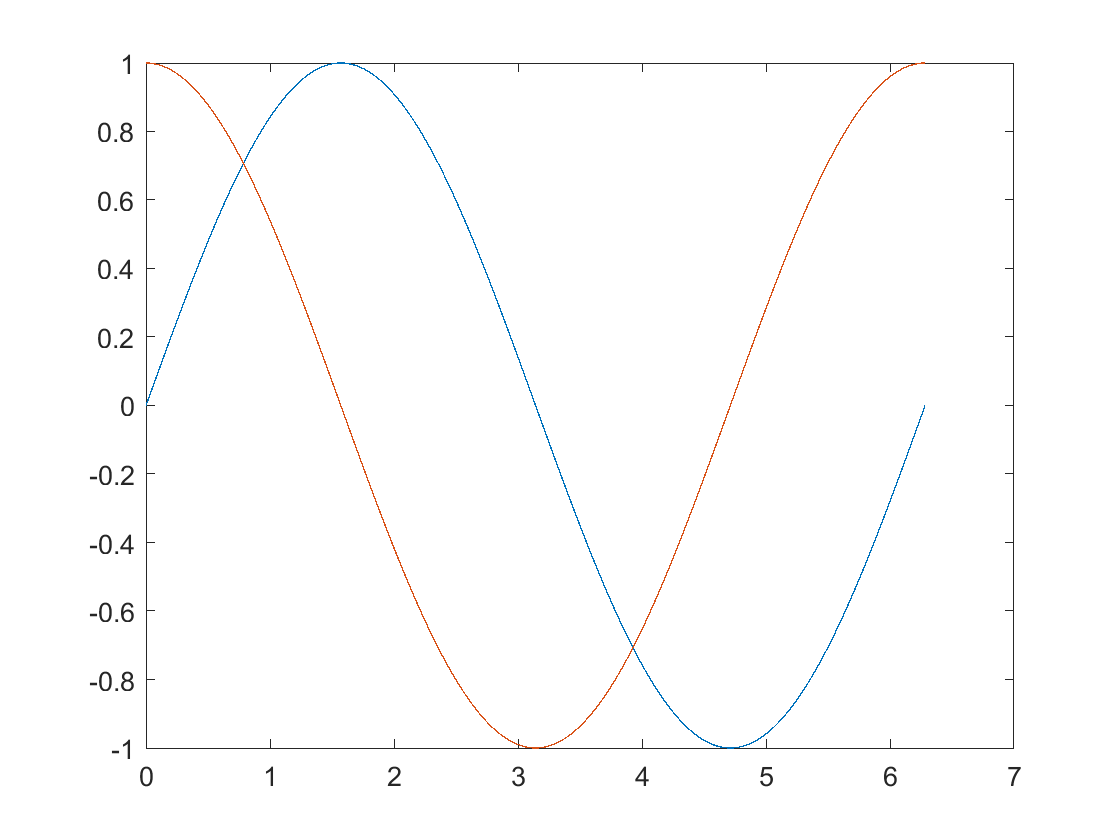

y1 = cos(x);
plot(x,y,x,y1)

Alternatively, both data sets can be contained in 2-by-100 matrices for `x `and` y. `Calling `plot` with a matrix will plot each column individually

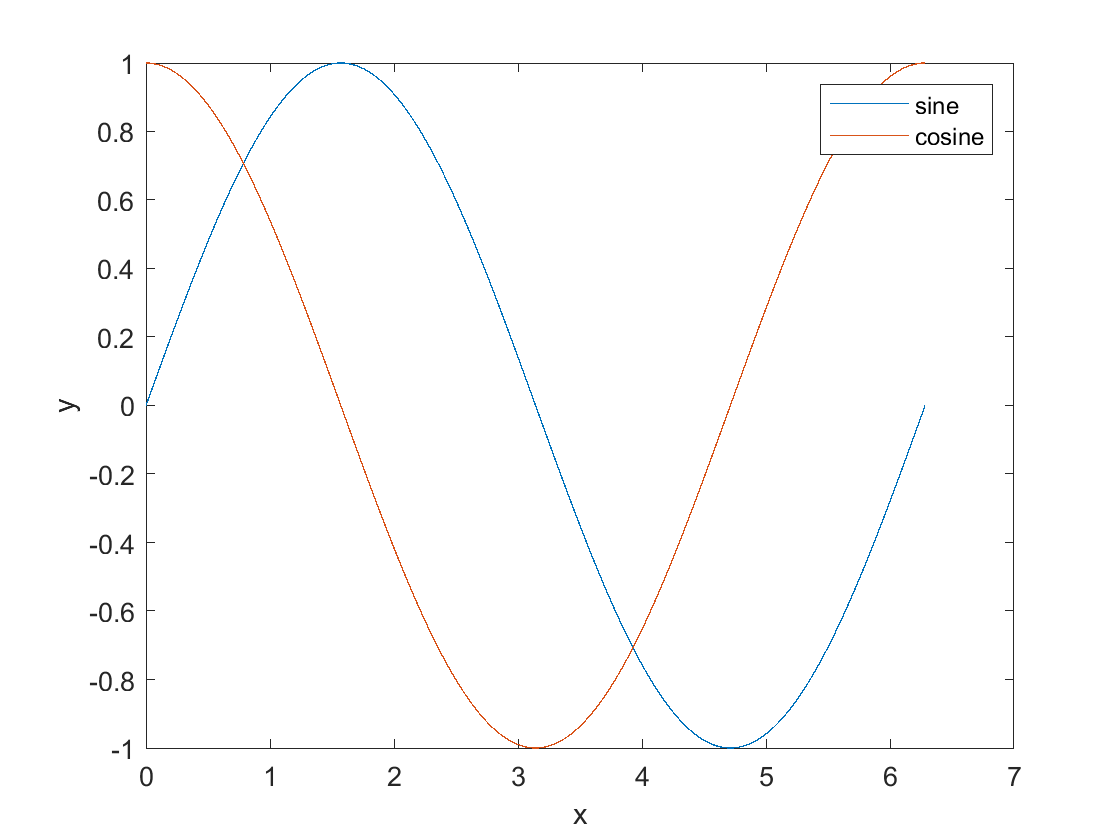

X = [x; x]';
Y = [y; y1]';
plot(X,Y)
xlabel('x')
ylabel('y')
legend("sine','cosine")

## Customizations

### Define Line Specifications

Create a line plot and use the *LineSpec* option to specify a dashed green line with square markers. Use `Name,Value` pairs to specify the line width, point marker size, and point marker colors. Set the marker edge color to blue and set the marker face color using an RGB color value.

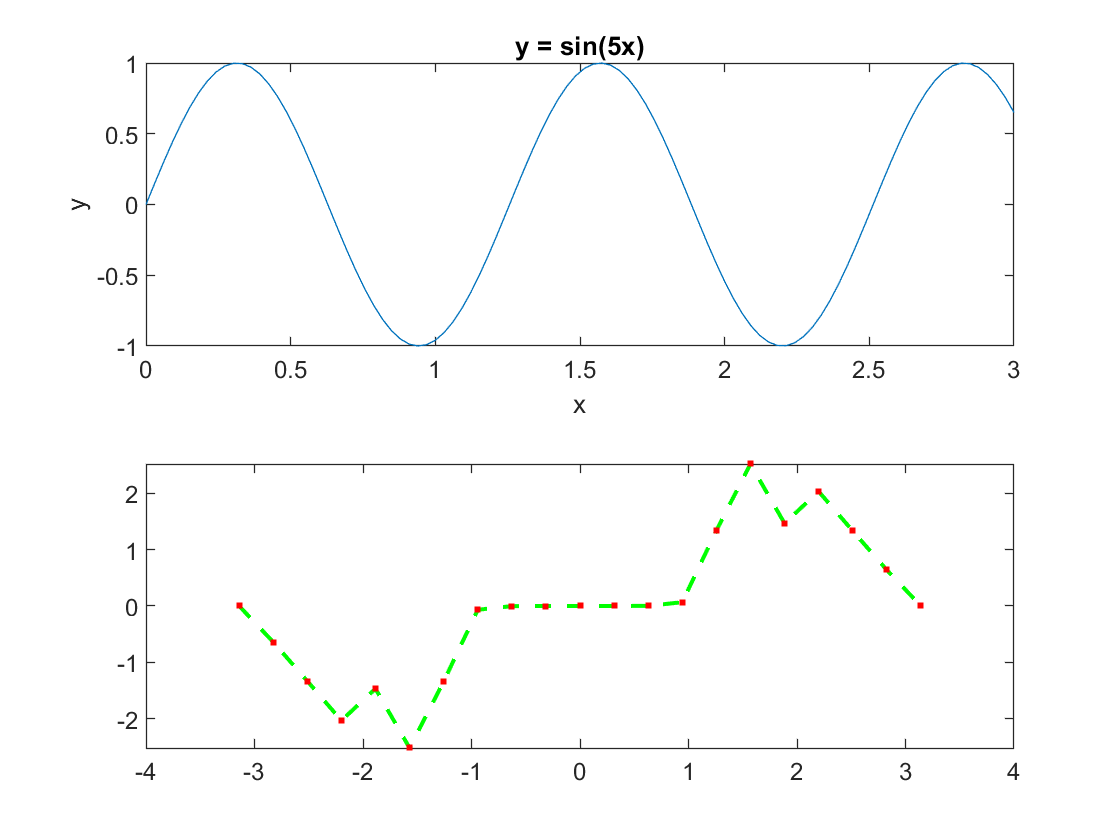

LineWidth = 1.5;
MarkerSize = 1.5;
MarkerEdgeColor = 'r';
x = -pi:pi/10:pi;
y = tan(sin(x)) - sin(tan(x));
p = plot(x,y,'--gs',...                             % Define the LineSpec as a dashed green line with points ('--gs')
    "LineWidth",LineWidth,...                       % Specify the line thickness
    "MarkerSize",MarkerSize,...                     % Specify the point marker size
    "MarkerEdgeColor",MarkerEdgeColor,...           % Set the point marker edge color
    "MarkerFaceColor",[0.5,0.5,0.5]);               % Set the point marker fill color

### Display Multiple Plots in a Figure Window

Call the `tiledlayout` function to create a 2-by-1 tiled chart layout. Call the `nexttile` function to create an axes object and return the object as `ax1`. Create the top plot by passing `ax1` to the `plot` function. Add a title and *y*-axis label to the plot by passing the axes to the `title` and `ylabel` functions. Repeat the process to create the bottom plot.

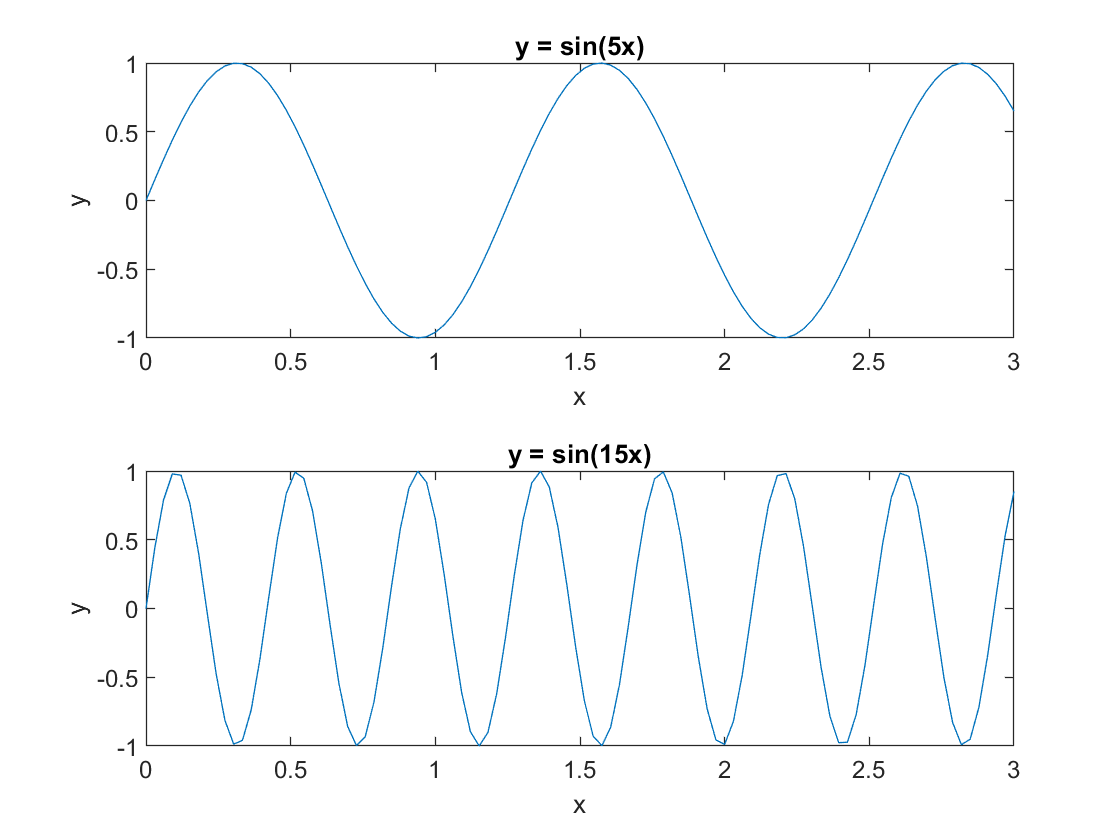

% Create data and 2-by-1 tiled chart layout
x = linspace(0,3);
y1 = sin(5*x);
y2 = sin(15*x);
tiledlayout(2,1)

% Top plot
ax1 = nexttile;
plot(ax1,x,y1)
title(ax1,"y = sin(5x)")
ylabel(ax1,'y')
xlabel(ax1,'x')

% Bottom plot
ax2 = nexttile;
plot(ax2,x,y2)
title(ax2,"y = sin(15x)")
ylabel(ax2,'y')
xlabel('x')

## Additional Information

### Get All Plot Properties

Graphics objects in MATLAB have many properties. To see all the properties of a plot, uncomment the following code

% get(p(1))

    AlignVertexCenters: off
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: off
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: on
                 Color: [0 1 0]
             ColorMode: 'manual'
           ContextMenu: [0×0 GraphicsPlaceholder]
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: on
         Interruptible: on
              LineJoin: 'round'
             LineStyle: '--'
         LineStyleMode: 'manual'
             LineWidth: 1.5000
                Marker: 'square'
       MarkerEdgeColor: [1 0 0]
       MarkerFaceColor: [0.5000 0.5000 0.5000]
         MarkerIndices: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21]
            MarkerMode: 'manual'
            MarkerSize: 1.5000
           

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[plot](https://www.mathworks.com/help/matlab/ref/plot.html)